# **Sinal Senoidal**

Para criar um sinal de teste senoidal, primeiramente é necessário determinar a frequência da onda. Por exemplo, desejamos gerar um sinal senoidal com f = 10 Hz e com amplitude mínima e máxima de -1 V e 1 V, respectivamente. 

f = 10; % Hz, frequência da onda senoidal 
V = 1; % V, amplitude da onda senoidal

Após determinados a frequência e amplitude, o próximo passo é determinar a taxa de amostragem. Respeitando o Teorema de amostragem de Nyquist-Shannon, para reproduzir o sinal fielmente no domínio da frequência é necessário que a taxa de amostragem *fs *seja igual ou maior que pelo menos duas vezes a frequência máxima *fm *$\left(fs\ge 2\cdot fm\right)\ldotp \;$A taxa de sobreamostragem é utilizada aumentar a taxa de amostragem além do mínimo exigido pelo teorema de Nyquist-Shannon. 

overSampRate = 30; % taxa de sobreamostragem
fs = overSampRate*f; % taxa de amostragem

O deslocamento de fase também pode ser especificado, este ângulo de fase controla o quão "adiantada" ou "atrasada" a onda senoidal está em relação ao tempo. 

phase = 1/3*pi; % deslocamento de fase em radianos

O próximo passo é determinar o número de ciclos desejados para o sinal e a base de tempo para representação do tempo ao longo dos ciclos completos da onda senoidal. 

nCyl = 5; % gera cinco ciclos da onda
t = 0:1/fs:nCyl*1/f-1/fs; % tempo base

Agora basta representar o sinal e plotar o mesmo.

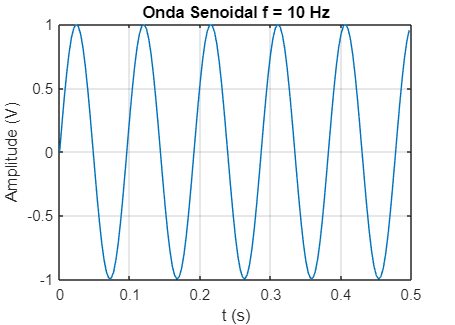

g = V*sin(2*pi*f*t*phase); % equação do sinal 

plot(t,g); % plota o sinal
grid on; % mostra linhas de grade
title(['Onda Senoidal f = ', num2str(f), ' Hz']); % adiciona título
xlabel('t (s)'); % adiciona título no eixo x
ylabel('Amplitude (V)'); % adiciona título no eixo y